clear

buf_len = 1e5;

az_max = 2^15 - 1;
el_max = 2^13 - 1;
r_max = 2^17 - 1;

az_min = 0;
el_min = -2^10 - 1;
r_min = 100;

in_code = [az_max - az_min, el_max - el_min, r_max - r_min] .* rand(buf_len,3) + [az_min, el_min, r_min];
in_code = round(in_code, 0);

% in_code = [6546, 4243, 490];
% in_code(2,:) = [6546, 4243, 490];
% in_code(3,:) = [6546, 4243, 490];

in_sph = code2deg(in_code);
in_card = sphdeg2card(in_sph);

ind_del = in_card(:,3) > 1e6 |...
    (in_card(:,1).^2 + in_card(:,2).^2 < 100^2) |...
    in_sph(:,2) > 80;
in_card(ind_del,:) = [];
in_sph(ind_del,:) = [];
in_code(ind_del,:) = [];
clear ind_del

out_code = zeros(length(in_code), 3);
for i=1:length(in_code)
    [out_code(i,1), out_code(i,2), out_code(i,3)] =...
        ParalaxCalc(in_code(i,1), in_code(i,2), in_code(i,3));
end

out_sph = code2deg(out_code);
out_ref_code = zeros(length(in_code), 3);
[out_ref_code(:,1), out_ref_code(:,2), out_ref_code(:,3)] =...
        ParalaxCalcRef(in_code(:,1), in_code(:,2), in_code(:,3));
out_ref_sph = code2deg(out_ref_code);

delta_ref = abs(out_sph - out_ref_sph);
delta_ref((delta_ref(:,1) > 180),1) = 360 - delta_ref((delta_ref(:,1) > 180),1);
[max_delta, ind] = max(delta_ref,[],1);
disp(['delta Az: ', num2str(max_delta(1)), ' in sph: ', num2str(in_sph(ind(1),:))]);

delta Az: 0.0054931 in sph: 245.093994      34.0795898           80393


disp(['delta El: ', num2str(max_delta(2)), ' in sph: ', num2str(in_sph(ind(2),:))]);

delta El: 0.0054931 in sph: 3.5925293       6.9543457           75959


disp(['delta R: ', num2str(max_delta(3)), ' in sph: ', num2str(in_sph(ind(3),:))]);

delta R: 0.49999 in sph: 303.3105469      33.43139648           119795


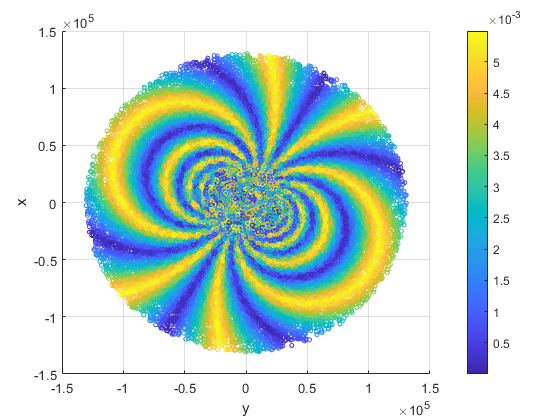



[out_card(:,1), out_card(:,2), out_card(:,3)] = sph2cart(deg2rad(out_sph(:,1)), deg2rad(out_sph(:,2)), out_sph(:,3));
[out_ref_card(:,1),out_ref_card(:,2),out_ref_card(:,3)] = sph2cart(deg2rad(out_ref_sph(:,1)), deg2rad(out_ref_sph(:,2)), out_ref_sph(:,3));


base_card = [29, 17, 11];

figure("Name","Az_Error")
scatter3(out_card(:,1),out_card(:,2),out_card(:,3), 10, delta_ref(:,1));

xlabel("x");
ylabel("y");
zlabel("z");
text(0,0,0,"mrl");
text(base_card(1), base_card(2), base_card(3), "kama");
colorbar

view([90 -90])

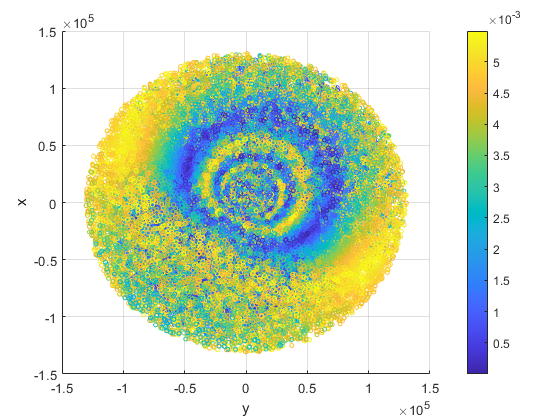


figure("Name","At_Error")
scatter3(out_card(:,1),out_card(:,2),out_card(:,3), 10, delta_ref(:,2));

xlabel("x");
ylabel("y");
zlabel("z");
text(0,0,0,"mrl");
text(base_card(1), base_card(2), base_card(3), "kama");
colorbar

view([90 -90])

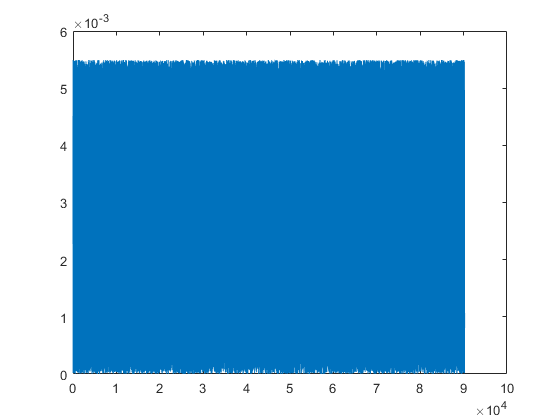



figure('Name', "Az_delta")
plot(delta_ref(:,1));

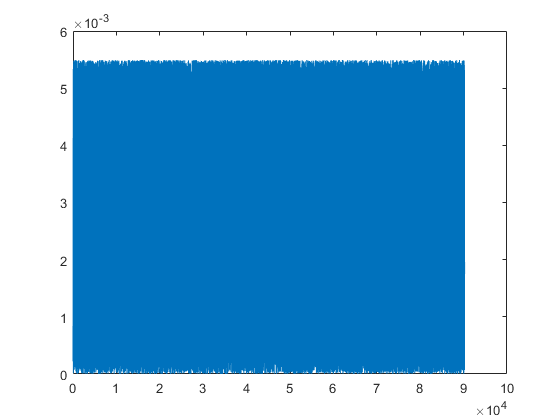

figure('Name', "At_delta")
plot(delta_ref(:,2));